yd=0.32;
m=0.102;

A=[0 1 0;14.41 -0.1961 13.02; 0 0 -250];
B=[0;0;50];
C=[1 0 0];
D=0;
I=eye(3);
syms s
G=C*inv(s*I-A)*B+D

$$G = \frac{6510000}{10000\,s^{3}+2501961\,s^{2}+346150\,s-36025000}$$

G=tf(6510000,[10000 2501961 346150 -36025000])


G =
 
                     6.51e06
  ----------------------------------------------
  10000 s^3 + 2.502e06 s^2 + 346150 s - 3.603e07
 
Continuous-time transfer function.



2)

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.



GC=187.862 + 349.54 * (1/s) + (22.6285 *2000)/(1+(2000/s))


GC =
 
  4.544e04 s^2 + 3.761e05 s + 699080
  ----------------------------------
             s^2 + 2000 s
 
Continuous-time transfer function.



3)

zero pole placement

T=0.004

G1dpz = c2d(GC,0.004,'matched')


G1dpz =
 
  5775 z^2 - 1.136e04 z + 5587
  ----------------------------
      z^2 - z + 0.0003355
 
Sample time: 0.004 seconds
Discrete-time transfer function.



T=0.015

G2dpz = c2d(GC,0.015,'matched')


G2dpz =
 
  1612 z^2 - 3031 z + 1424
  ------------------------
    z^2 - z + 9.358e-14
 
Sample time: 0.015 seconds
Discrete-time transfer function.



T=0.009

G3dpz = c2d(GC,0.009,'matched')


G3dpz =
 
  2621 z^2 - 5051 z + 2433
  ------------------------
    z^2 - z + 1.523e-08
 
Sample time: 0.009 seconds
Discrete-time transfer function.



bilinear

T=0.004

G1dbl = c2d(GC,0.004,'tustin')


G1dbl =
 
  9240 z^2 - 1.818e04 z + 8939
  ----------------------------
       z^2 - 0.4 z - 0.6
 
Sample time: 0.004 seconds
Discrete-time transfer function.



T=0.015

G2dbl = c2d(GC,0.015,'tustin')


G2dbl =
 
  3019 z^2 - 5676 z + 2666
  ------------------------
   z^2 - 0.125 z - 0.875
 
Sample time: 0.015 seconds
Discrete-time transfer function.



T=0.009

G3dbl = c2d(GC,0.009,'tustin')


G3dbl =
 
  4715 z^2 - 9086 z + 4377
  ------------------------
     z^2 - 0.2 z - 0.8
 
Sample time: 0.009 seconds
Discrete-time transfer function.



4)

T=0.004

Gpz = c2d(G,0.004,'tustin')


Gpz =
 
                                                
  3.471e-06 z^3 + 1.041e-05 z^2 + 1.041e-05 z   
                                                
                                     + 3.471e-06
                                                
  ----------------------------------------------
                                          
        z^3 - 2.333 z^2 + 1.666 z - 0.3331
                                          
 
Sample time: 0.004 seconds
Discrete-time transfer function.



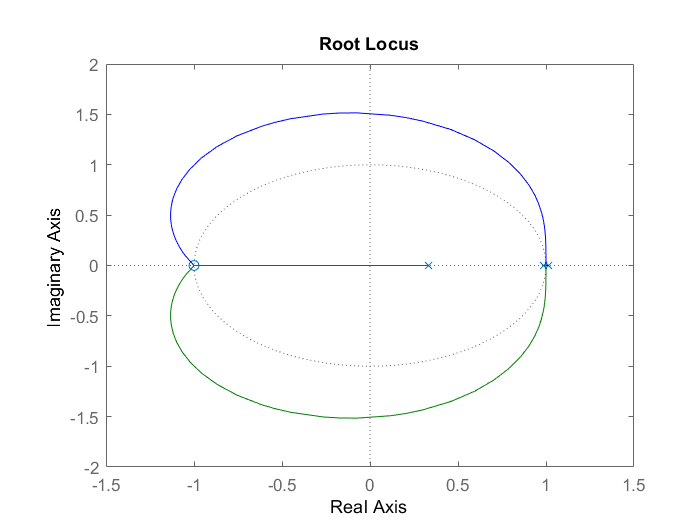

rlocus(Gpz)

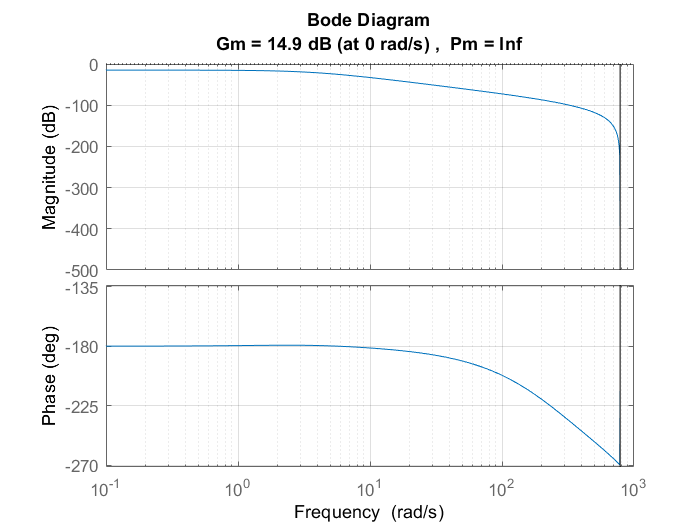

margin(Gpz)
grid on

fb = bandwidth( Gpz )

fb = 2.4368

5)

Gdz


Gdz =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 252, Ki = 166, Kd = 33.7, Tf = 0.0021, Ts = 0.004
 
Sample time: 0.004 seconds
Discrete-time PIDF controller in parallel form.



6)

Gdz


Gdz =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 252, Ki = 166, Kd = 33.7, Tf = 0.0021, Ts = 0.004
 
Sample time: 0.004 seconds
Discrete-time PIDF controller in parallel form.



Gtz=Gdz*Gpz


Gtz =
 
                                                
  0.0564 z^5 + 0.05807 z^4 - 0.1095 z^3         
                                                
              - 0.1128 z^2 + 0.05308 z + 0.05474
                                                
  ----------------------------------------------
                                                
  z^5 - 2.433 z^4 + 0.9981 z^3 + 1.601 z^2      
                                                
                              - 1.466 z + 0.2999
                                                
 
Sample time: 0.004 seconds
Discrete-time transfer function.



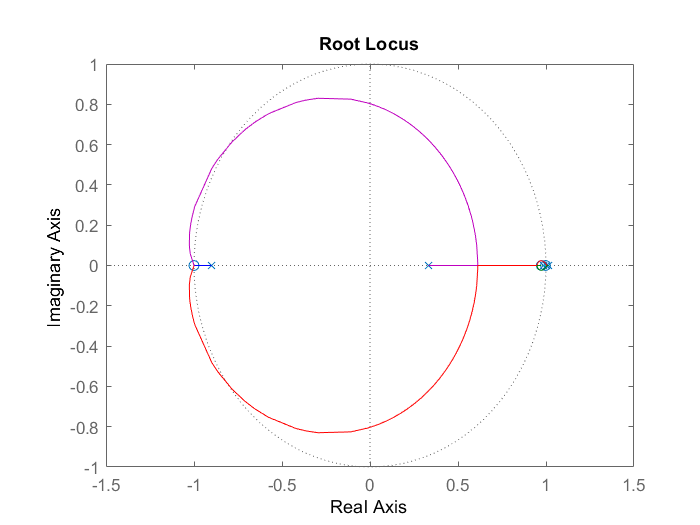

rlocus(Gtz)

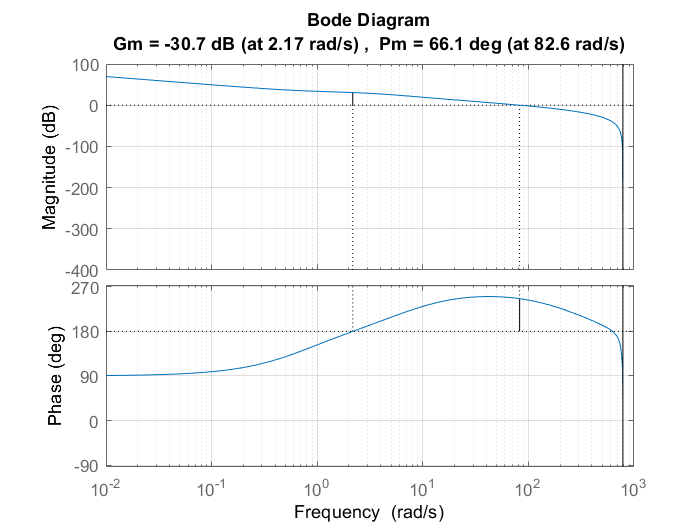

margin(Gtz)
grid on

7)

num = [0.0000108 0.00003241 0.00003241 0.0000108];      
den = [1 -2.282 1.564 -0.2821]; 
sys = tf(num, den)

sys_poles = roots(den)
sys_zeros = zero(sys)

syms z
F = 1 - ((1-z^(-1))*(1-1.0117*z^(-1))*(1+1.0309*z^(-1)))
expanded_expr = expand(F)

num_f = [0 0.9808 1.0622 -1.043]
den_f = [1 0 0 0]
Fz = tf(num_f, den_f)

Gd = Fz / ((1 - Fz) * sys)

9)

T = 0.004

sys = ss(A,B,C,D);
sysd=c2d(sys,0.004);
[Az,Bz,Cz,Dz] = dssdata(sysd)

Az =     1.0001    0.0040    0.0001
    0.0576    0.9993    0.0329
         0         0    0.3679


Bz =     0.0000
    0.0038
    0.1264


Cz =      1     0     0


Dz = 0

Controllability

M= ctrb(Az,Bz)

M =     0.0000    0.0000    0.0001
    0.0038    0.0080    0.0095
    0.1264    0.0465    0.0171


rank_m=rank(M)

rank_m = 3

Observability

N= obsv(Az,Cz)

N =     1.0000         0         0
    1.0001    0.0040    0.0001
    1.0005    0.0080    0.0002


rank_n=rank(N)

rank_n = 3

10)

p = [0 0 0];
K = acker(Az,Bz,p)

K =    1.0e+04 *

    3.7999    0.0291    0.0008


sys_new = ss(A-B*K,B,C,D);
sysd_new=c2d(sys_new,0.004);
[Az_new,Bz_new,Cz_new,Dz_new] = dssdata(sysd_new)

Az_new =    1.0e+03 *

    0.0009    0.0000    0.0000
   -0.0768    0.0003    0.0000
   -1.4545   -0.0170   -0.0002


Bz_new =     0.0000
    0.0020
    0.0383


Cz_new =      1     0     0


Dz_new = 0

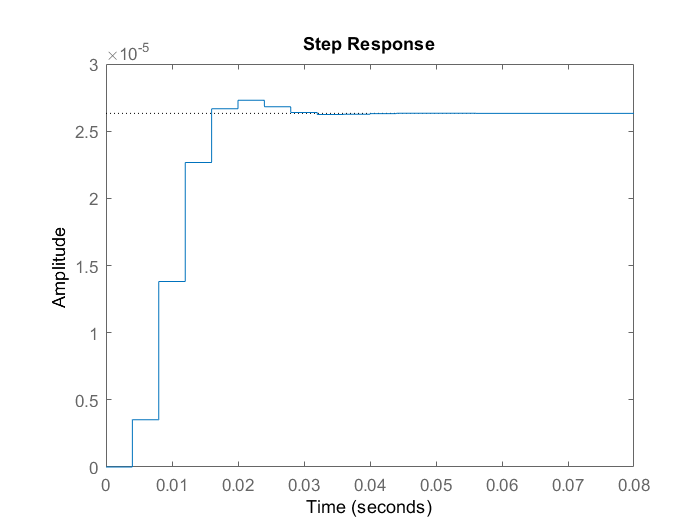

stepplot(sysd_new)

11)

eig(Az)

ans =     1.0149
    0.9845
    0.3679


the poles of the observer should be smaller than the system ( observer must be faster then the system)

po=[0.003 0.002 0.001];
L=place(Az',Cz',po);
L=L'

L =     2.3613
  362.2701
  588.6679
